# Maximise the MATLAB Peaks Function

## Section 1.0 - Set Up

If the "Random" option is selected from the drop down menu on line 4, then a space-filling design ( Sobol sequence generator) is generated of the size selected in the edit box on line 9 of the code. Alternatively, if the "Fixed" option is selected from the drop down menu, then a constant design is used. In either case, we assume the form of ***f(x)*** is unknown, and iid normally distributed noise with a standaard deviation of 0.2 is added to the data - mimicing the act of sampling by measurement. Thus, even using the "Fixed" design, different results will be generated each time the live script is run.

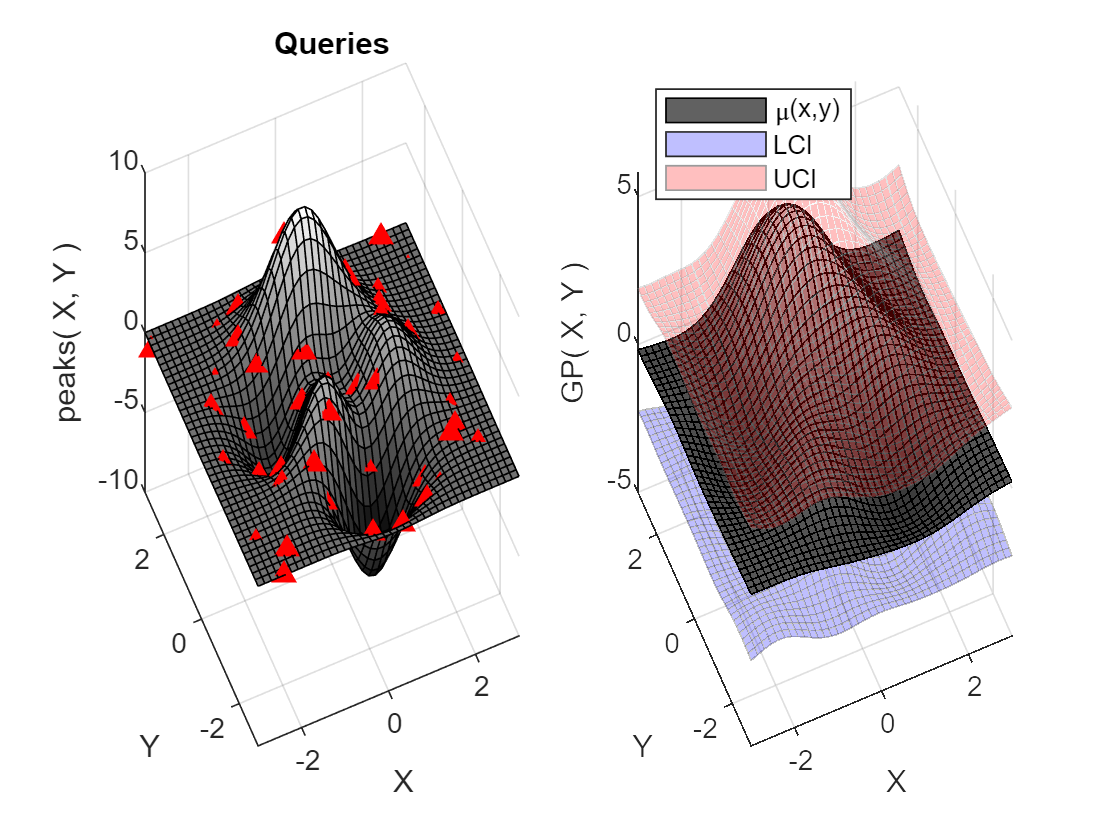

clc
clear
%---------------------------------------------------------------------
% Select the acquisition function
%---------------------------------------------------------------------
AcqFcn = "aei";
[ X, Y, Z ] = peaks( 40 );
Selection = "Random";
if contains( "Random", Selection )
    %-----------------------------------------------------------------
    % Generate 2-D Sobol sequence - space-filling design
    %-----------------------------------------------------------------
    DesignSize = 45;
    H = sobolset( 2 );
    Hs = scramble( H, "MatousekAffineOwen" );
    D = net( Hs, DesignSize );
    %-----------------------------------------------------------------
    % Map the design to the interval [ -3, 3 ]
    %-----------------------------------------------------------------
    D = [ 6, 6 ] .* ( D ) - [ 3, 3];
else
    %-----------------------------------------------------------------
    % Use fixed data leading to the global maximum
    %-----------------------------------------------------------------
    D = [-2.888	2.182	-1.084	0.197	-1.742	2.541	-0.731	1.338	-2.507	1.802	-1.489	0.601	-2.145	2.946	-0.351	0.957	-2.706	2.000	-0.892	0.004
         -1.253	0.789	2.817	-2.554	0.341	-0.618	-1.591	2.040	1.746	-2.219	-0.168	0.468	-2.661	2.376	1.426	-0.939	1.093	-1.370	-2.343	2.792].';
end
x = D( :, 1 );
y = D( :, 2 );
figure;
Ax = subplot( 1,2,1);
surface( Ax, X, Y, Z );
view([-23.44 40.88])
colormap( Ax, "gray" )
Ax.NextPlot = "add";
Sigma = 0.2;
z = peaks( x, y ) +  Sigma*randn( size(x) );
plot3( x, y, z, 'r^', 'MarkerFacecolor', 'red');
grid on
xlabel( "X" );
ylabel( "Y" );
zlabel( "peaks( X, Y )");
title( Ax, "Queries" );
B = bayesOpt( "gpr", AcqFcn );
%-----------------------------------------------------------------
% Define the data coding: [-3, 3] --> [ -1, 1]
%-----------------------------------------------------------------
B = B.conDataCoding( [-3, -3 ], [ 3, 3 ] );
%-----------------------------------------------------------------
% Set the training data and train the model
%-----------------------------------------------------------------
B = B.setTrainingData( [x, y], z );   
%-----------------------------------------------------------------
% Plot the predictions
%-----------------------------------------------------------------
Ax( 2 ) = subplot( 1, 2, 2 );
[ Zp, ~, Zint ] = B.predict( [ X(:), Y(:) ] );
Zp = reshape( Zp, size( X ) );
Ax( 2 ).NextPlot = "add";
colormap( Ax( 2 ), "gray" );
surf( X, Y, Zp );
M = mesh( X, Y, reshape( Zint(:,1), size( Y ) ) );
M.FaceColor = 'blue';
M(2) = mesh( X, Y, reshape( Zint(:,2), size( Y ) ) );
M(2).FaceColor = 'red';
for Q = 1:2
    % Make ci meshes transparent
    M( Q ).FaceAlpha = 0.25;
    M( Q ).EdgeAlpha = 0.25;
end
view([-23.44 40.88]);
grid on;
xlabel( Ax(2), "X" );
ylabel( Ax(2), "Y" );
zlabel( Ax(2), "GP( X, Y )");
legend( "\mu(x,y)", "LCI", "UCI", "Location", "northwest" );

I = 0;

## SECTION 2.0 - Define bayesOpt Object & Perform Algorithm Iteration 1.0

I = I + 1;
B = B.acqFcnMaxTemplate( "lb", B.Xlo, "ub", B.Xhi );

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3   -1.914824e-02    0.000e+00    6.742e-02
    1       6   -2.418372e-02    0.000e+00    6.538e-02    6.887e-02
    2       9   -3.252542e-02    0.000e+00    4.139e-02    3.544e-01
    3      12   -3.467189e-02    0.000e+00    7.643e-03    1.269e-01
    4      15   -3.478601e-02    0.000e+00    4.893e-03    2.274e-02
    5      18   -3.480700e-02    0.000e+00    3.703e-03    6.751e-03
    6      21   -3.482755e-02    0.000e+00    9.996e-04    1.839e-02
    7      24   -3.482916e-02    0.000e+00    2.023e-04    3.098e-03
    8      27   -3.482926e-02    0.000e+00    2.862e-06    9.437e-04
    9      30   -3.482926e-02    0.000e+00    2.000e-06    8.274e-06
   10      33   -3.482926e-02    0.000e+00    2.002e-08    9.130e-06

Local minimum found that satisfies the cons

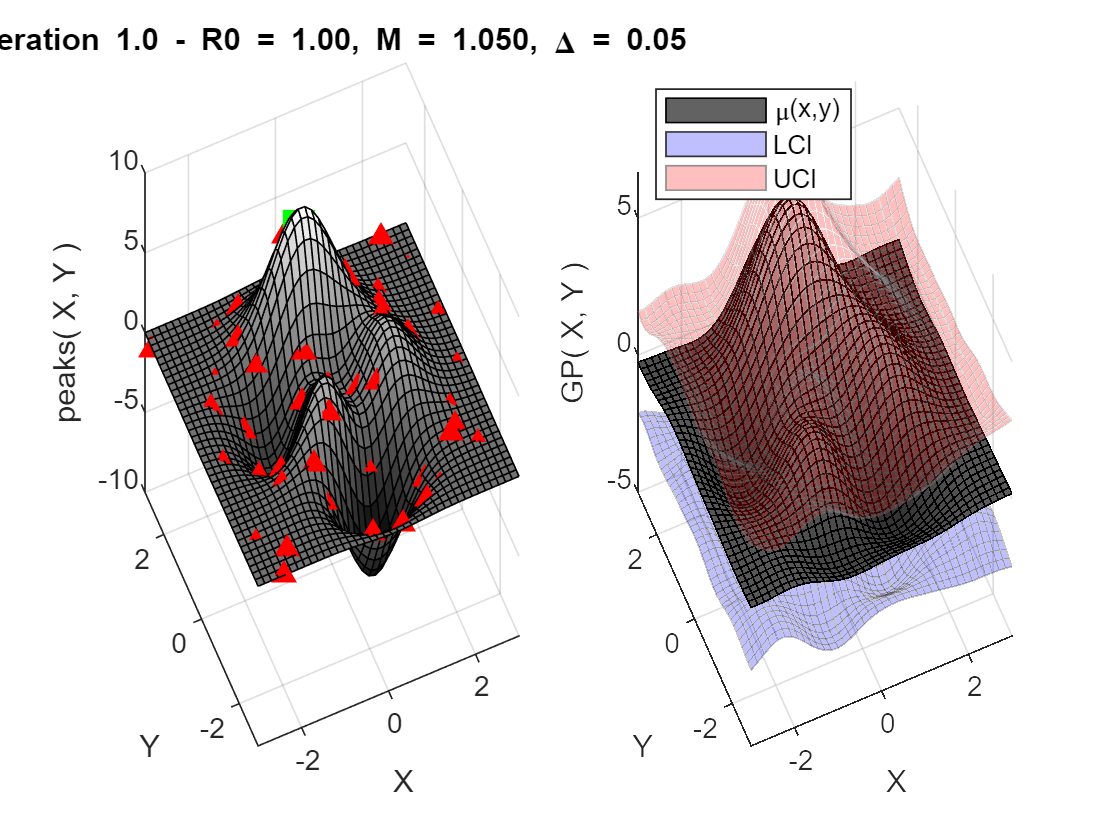

Znext = peaks( B.Xnext(1), B.Xnext(2) ) + Sigma*randn( 1 );
B = B.addNewQuery( B.Xnext, Znext );
figure;
Ax = subplot( 1,2,1);
surface( Ax, X, Y, Z );
view([-23.44 40.88])
colormap( Ax, "gray" )
Ax.NextPlot = "add";
plot3( B.X(:,1), B.X(:,2), B.Y, 'r^', 'MarkerFacecolor', 'red');
plot3( Ax(1), B.Xnext(1), B.Xnext(2), Znext, 'gs', 'MarkerSize', 12, 'MarkerFaceColor', 'green' );
grid on
xlabel( "X" );
ylabel( "Y" );
zlabel( "peaks( X, Y )");
if contains( AcqFcn, "aei", "IgnoreCase", true )
    HP = B.HyperPar;
    Tstr = sprintf( "Iteration %3.1f - R0 = %4.2f, M = %5.3f, \\Delta = %4.2f",...
                    I, HP(1), HP(2), HP(3) );
else
    Tstr = sprintf( "Iteration %3.1f - \\beta = %5.4f", I, B.HyperPar );
end
title( Ax, Tstr );
Ax( 2 ) = subplot( 1, 2, 2 );
[ Zp, ~, Zint ] = B.predict( [ X(:), Y(:) ] );
Zp = reshape( Zp, size( X ) );
Ax( 2 ).NextPlot = "add";
colormap( Ax( 2 ), "gray" );
surf( X, Y, Zp );
M = mesh( X, Y, reshape( Zint(:,1), size( Y ) ) );
M.FaceColor = 'blue';
M(2) = mesh( X, Y, reshape( Zint(:,2), size( Y ) ) );
M(2).FaceColor = 'red';
for Q = 1:2
    % Make ci meshes transparent
    M( Q ).FaceAlpha = 0.25;
    M( Q ).EdgeAlpha = 0.25;
end
view([-23.44 40.88]);
grid on;
xlabel( Ax(2), "X" );
ylabel( Ax(2), "Y" );
zlabel( Ax(2), "GP( X, Y )");
legend( "\mu(x,y)", "LCI", "UCI", "Location", "northwest" );

## SECTION 3.0 - Subsequent Iterations

I = I + 1;
B = B.acqFcnMaxTemplate( "lb", [ -3, -3], "ub", [ 3, 3 ]);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3   -3.987559e-02    0.000e+00    1.221e-01
    1       6   -4.710341e-02    0.000e+00    6.175e-02    1.749e-01
    2       9   -4.860804e-02    0.000e+00    4.045e-03    5.278e-02
    3      12   -4.861893e-02    0.000e+00    1.532e-03    5.031e-03
    4      15   -4.861953e-02    0.000e+00    7.960e-04    1.213e-03
    5      18   -4.861980e-02    0.000e+00    1.612e-04    6.213e-04
    6      21   -4.861980e-02    0.000e+00    1.614e-06    4.422e-05
    7      24   -4.861980e-02    0.000e+00    1.905e-08    9.979e-07

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

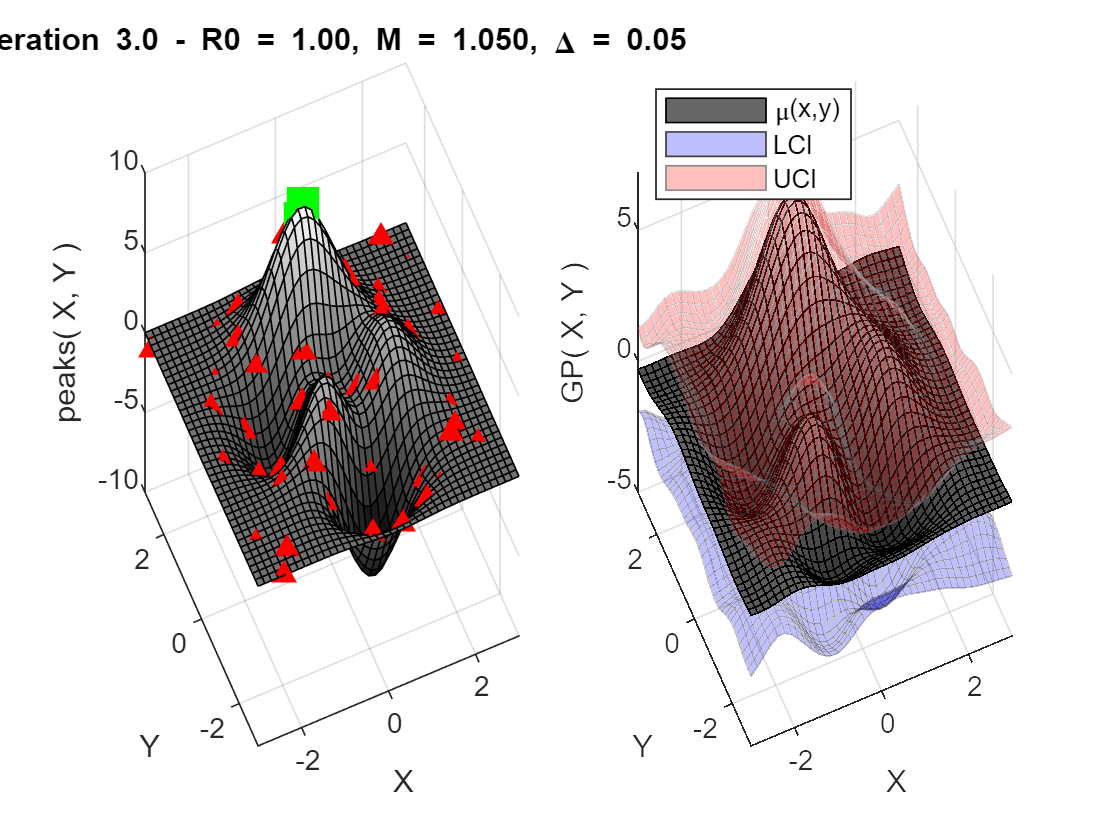

Znext = peaks( B.Xnext(1), B.Xnext(2) ) + Sigma*randn( 1 );
B = B.addNewQuery( B.Xnext, Znext );
plot3( Ax(1), B.Xnext(1), B.Xnext(2), Znext, 'gs', 'MarkerSize', 12, 'MarkerFaceColor', 'green' );

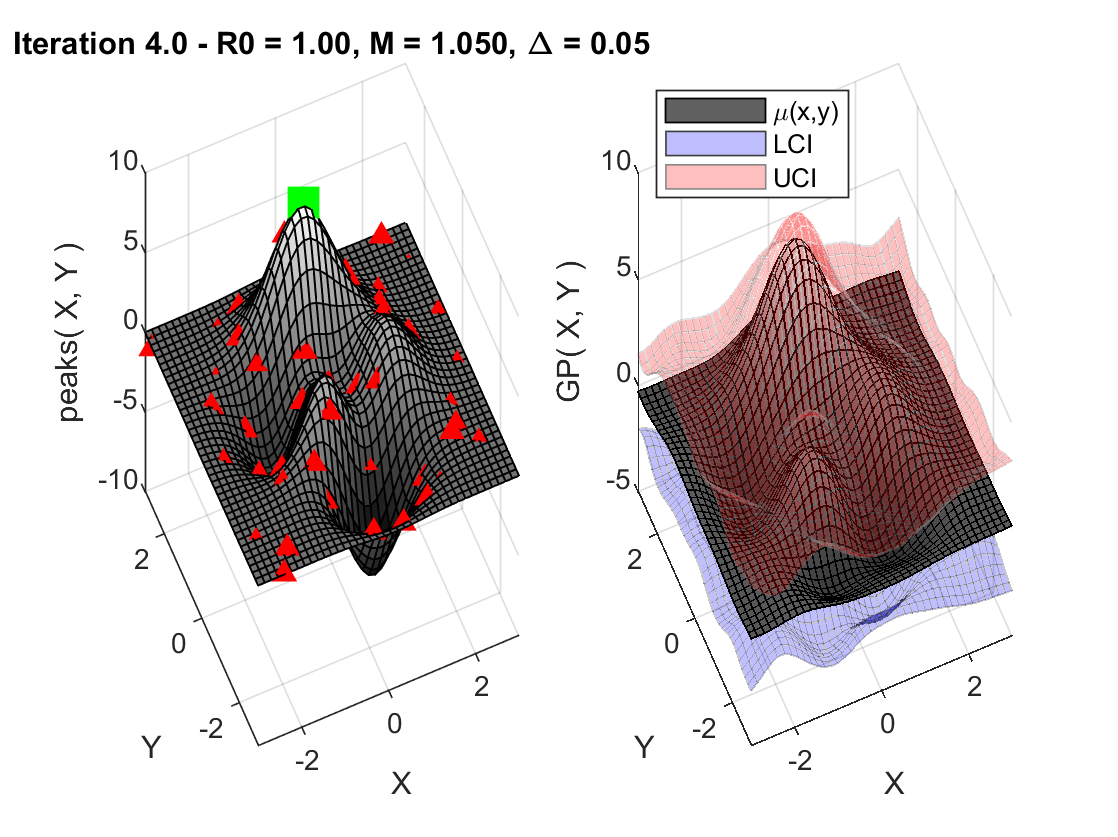

figure;
Ax = subplot( 1,2,1);
surface( Ax, X, Y, Z );
view([-23.44 40.88])
colormap( Ax, "gray" )
Ax.NextPlot = "add";
plot3( B.X(:,1), B.X(:,2), B.Y, 'r^', 'MarkerFacecolor', 'red');
plot3( Ax(1), B.Xnext(1), B.Xnext(2), Znext, 'gs', 'MarkerSize', 12, 'MarkerFaceColor', 'green' );
grid on
xlabel( "X" );
ylabel( "Y" );
zlabel( "peaks( X, Y )");
if contains( AcqFcn, "aei", "IgnoreCase", true )
    HP = B.HyperPar;
    Tstr = sprintf( "Iteration %3.1f - R0 = %4.2f, M = %5.3f, \\Delta = %4.2f",...
                    I, HP(1), HP(2), HP(3) );
else
    Tstr = sprintf( "Iteration %3.1f - \\beta = %5.4f", I, B.HyperPar );
end
title( Ax, Tstr );
Ax( 2 ) = subplot( 1, 2, 2 );
[ Zp, ~, Zint ] = B.predict( [ X(:), Y(:) ] );
Zp = reshape( Zp, size( X ) );
Ax( 2 ).NextPlot = "add";
colormap( Ax( 2 ), "gray" );
surf( X, Y, Zp );
M = mesh( X, Y, reshape( Zint(:,1), size( Y ) ) );
M.FaceColor = 'blue';
M(2) = mesh( X, Y, reshape( Zint(:,2), size( Y ) ) );
M(2).FaceColor = 'red';
for Q = 1:2
    % Make ci meshes transparent
    M( Q ).FaceAlpha = 0.25;
    M( Q ).EdgeAlpha = 0.25;
end
view([-23.44 40.88]);
grid on;
xlabel( Ax(2), "X" );
ylabel( Ax(2), "Y" );
zlabel( Ax(2), "GP( X, Y )");
legend( "\mu(x,y)", "LCI", "UCI", "Location", "northwest" );